# FEM Linear Systems

# Free - Free Beam

### Free-Free Beam2

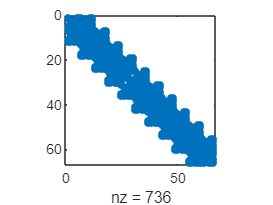

clear
close all

filepath = "./Sims/matrices";
prefix = "Beam-Beam2-FreeFree";
K = import_stiffness(strjoin([filepath, prefix + "_STIF1.mtx"], filesep));
M = import_mass(strjoin([filepath,      prefix + "_MASS2.mtx"], filesep));
f = import_load(strjoin([filepath,      prefix + "_LOAD3.mtx"], filesep));
[K, M, f] = prepare_linear_system(K, M, f);

spy(K);

bandwidth(K,"upper")

ans = 11

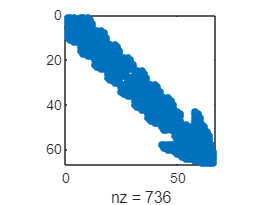

p = symrcm(K);
spy(K(p,p))

bandwidth(K(p,p),"upper")

ans = 15

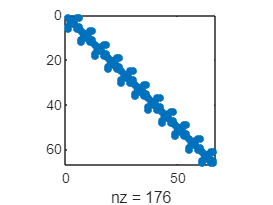

spy(M);


conditionNumber = condest(K)

conditionNumber = 2.4424e+19

null(full(K))

ans =     0.1923   -0.1592    0.1122    0.0671   -0.0333   -0.1020
    0.2177    0.1407   -0.1449   -0.0605   -0.1357    0.0358
   -0.0666    0.1523    0.0064    0.1786   -0.0905   -0.2093
    0.0302   -0.0772   -0.2137    0.1461    0.1304   -0.0041
    0.0001    0.0846   -0.0275   -0.0819    0.0891   -0.2451
   -0.1666   -0.1840   -0.0492   -0.0471   -0.1008   -0.0790
    0.1923   -0.1592    0.1122    0.0671   -0.0333   -0.1020
    0.2010    0.1223   -0.1499   -0.0652   -0.1458    0.0279
   -0.0666    0.1439    0.0092    0.1868   -0.0994   -0.1848
    0.0302   -0.0772   -0.2137    0.1461    0.1304   -0.0041


size(K)

ans =     66    66


numel(K)

ans = 4356

nnz(K)

ans = 736

nnz(K) / numel(K)

ans = 0.1690

eig(full(K), full(M))

ans = 	1.0e+09 *

   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0125
    0.0125
    0.0331
    0.0673


### Free-Free Beam3

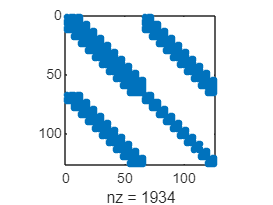

clear
close all

filepath = "./Sims/matrices";
prefix = "Beam-Beam3-FreeFree";
K = import_stiffness(strjoin([filepath, prefix + "_STIF1.mtx"], filesep));
M = import_mass(strjoin([filepath,      prefix + "_MASS2.mtx"], filesep));
f = import_load(strjoin([filepath,      prefix + "_LOAD3.mtx"], filesep));
[K, M, f] = prepare_linear_system(K, M, f);

spy(K);

bandwidth(K,"upper")

ans = 71

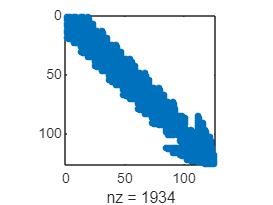

p = symrcm(K);
spy(K(p,p))

bandwidth(K(p,p),"upper")

ans = 27

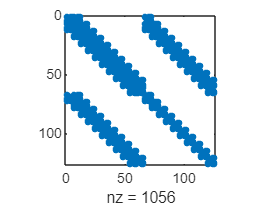

spy(M);


conditionNumber = condest(K)

conditionNumber = 1.5079e+19

null(full(K))

ans =     0.1892   -0.0510    0.0828    0.0115    0.0468    0.0073
    0.0919    0.0593   -0.0682   -0.1016   -0.1698    0.0526
   -0.0720   -0.0774    0.1782   -0.0913   -0.0850   -0.0066
    0.0010   -0.0850   -0.0783   -0.1596    0.0866   -0.0363
   -0.0107    0.0948    0.1097   -0.0800   -0.0081   -0.1266
   -0.0174   -0.1065   -0.0178    0.0926   -0.0133   -0.1514
    0.1892   -0.0510    0.0828    0.0115    0.0468    0.0073
    0.0902    0.0486   -0.0700   -0.0923   -0.1711    0.0375
   -0.0709   -0.0869    0.1672   -0.0833   -0.0842    0.0061
    0.0010   -0.0850   -0.0783   -0.1596    0.0866   -0.0363


size(K)

ans =    126   126


numel(K)

ans = 15876

nnz(K)

ans = 1934

nnz(K) / numel(K)

ans = 0.1218

eig(full(K), full(M))

ans = 	1.0e+10 *

   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0013
    0.0013
    0.0033
    0.0072


### Free-Free Hex8

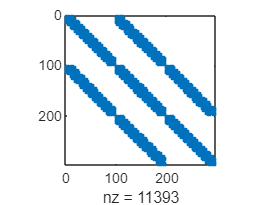

clear
close all

filepath = "./Sims/matrices";
prefix = "SolidBeam-Hex8-FreeFree";
K = import_stiffness(strjoin([filepath, prefix + "_STIF1.mtx"], filesep));
M = import_mass(strjoin([filepath,      prefix + "_MASS2.mtx"], filesep));
f = import_load(strjoin([filepath,      prefix + "_LOAD3.mtx"], filesep));
[K, M, f] = prepare_linear_system(K, M, f);

spy(K);

bandwidth(K,"upper")

ans = 113

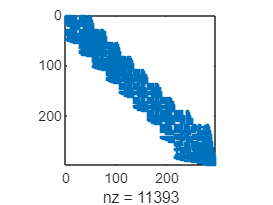

p = symrcm(K);
spy(K(p,p))

bandwidth(K(p,p),"upper")

ans = 67

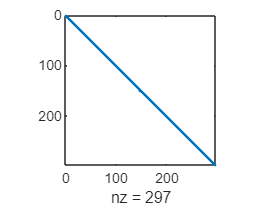

spy(M);


conditionNumber = condest(K)

conditionNumber = 3.8483e+19

null(full(K))

ans =     0.0166   -0.0276   -0.0601   -0.0335   -0.0344   -0.0710
    0.0543    0.1520   -0.0395    0.0540   -0.0025   -0.1039
    0.1290    0.0543   -0.0800    0.0278    0.0254    0.1181
    0.0037   -0.0472   -0.0653   -0.0244   -0.0319   -0.0541
    0.0543    0.1520   -0.0395    0.0540   -0.0025   -0.1039
    0.1326    0.0226   -0.0238    0.0118   -0.0308    0.1184
   -0.0091   -0.0667   -0.0705   -0.0153   -0.0294   -0.0373
    0.0543    0.1520   -0.0395    0.0540   -0.0025   -0.1039
    0.1363   -0.0090    0.0324   -0.0041   -0.0869    0.1187
    0.0166   -0.0276   -0.0601   -0.0335   -0.0344   -0.0710


size(K)

ans =    297   297


numel(K)

ans = 88209

nnz(K)

ans = 11393

nnz(K) / numel(K)

ans = 0.1292

eig(full(K), full(M))

ans = 	1.0e+09 *

   -0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0075
    0.0077
    0.0083
    0.0091


### Free-Free Hex20

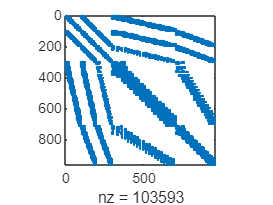

clear
close all

filepath = "./Sims/matrices";
prefix = "SolidBeam-Hex20-FreeFree";
K = import_stiffness(strjoin([filepath, prefix + "_STIF1.mtx"], filesep));
M = import_mass(strjoin([filepath,      prefix + "_MASS2.mtx"], filesep));
f = import_load(strjoin([filepath,      prefix + "_LOAD3.mtx"], filesep));
[K, M, f] = prepare_linear_system(K, M, f);

spy(K);

bandwidth(K,"upper")

ans = 779

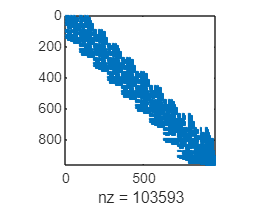

p = symrcm(K);
spy(K(p,p))

bandwidth(K(p,p),"upper")

ans = 187

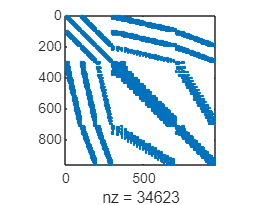

spy(M);


conditionNumber = condest(K)

conditionNumber = 4.1259e+18

null(full(K))

ans =    -0.0051   -0.0369   -0.0292    0.0150    0.0106   -0.0341
   -0.0442    0.0067   -0.0233   -0.0483    0.0910   -0.0190
   -0.0590    0.0571    0.0375   -0.0321   -0.0237   -0.0614
   -0.0038   -0.0361   -0.0187    0.0270    0.0037   -0.0318
   -0.0442    0.0067   -0.0233   -0.0483    0.0910   -0.0190
   -0.0193    0.0339    0.0432   -0.0490   -0.0392   -0.0592
   -0.0025   -0.0354   -0.0082    0.0390   -0.0031   -0.0296
   -0.0442    0.0067   -0.0233   -0.0483    0.0910   -0.0190
    0.0205    0.0107    0.0488   -0.0659   -0.0548   -0.0571
   -0.0051   -0.0369   -0.0292    0.0150    0.0106   -0.0341


size(K)

ans =    963   963


numel(K)

ans = 927369

nnz(K)

ans = 103593

nnz(K) / numel(K)

ans = 0.1117

eig(full(K), full(M))

ans = 	1.0e+10 *

   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0013
    0.0013
    0.0034
    0.0073


### Free-Free Tet4

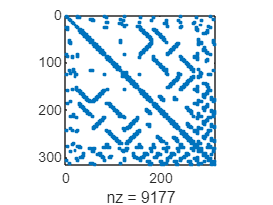

clear
close all

filepath = "./Sims/matrices";
prefix = "SolidBeam-Tet4-FreeFree";
K = import_stiffness(strjoin([filepath, prefix + "_STIF1.mtx"], filesep));
M = import_mass(strjoin([filepath,      prefix + "_MASS2.mtx"], filesep));
f = import_load(strjoin([filepath,      prefix + "_LOAD3.mtx"], filesep));
[K, M, f] = prepare_linear_system(K, M, f);

spy(K);

bandwidth(K,"upper")

ans = 305

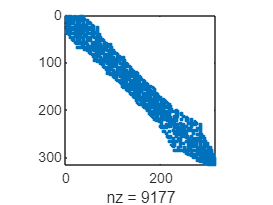

p = symrcm(K);
spy(K(p,p))

bandwidth(K(p,p),"upper")

ans = 56

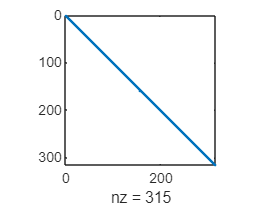

spy(M);


conditionNumber = condest(K)

conditionNumber = 3.7220e+18

null(full(K))

ans =     0.0339   -0.0349    0.0064   -0.0736    0.0564   -0.0142
   -0.0294   -0.0735   -0.0926    0.0105    0.0997    0.1141
    0.0184    0.1016   -0.0839   -0.0546   -0.0542    0.1201
    0.0182   -0.0246    0.0405   -0.0889    0.0164   -0.0218
   -0.0294   -0.0735   -0.0926    0.0105    0.0997    0.1141
    0.1457    0.0594   -0.0371    0.0124   -0.0900    0.0585
    0.0182   -0.0246    0.0405   -0.0889    0.0164   -0.0218
   -0.1077   -0.0221    0.0779   -0.0656   -0.1002    0.0760
    0.0249   -0.1223   -0.0530   -0.0120   -0.0576   -0.1302
    0.0339   -0.0349    0.0064   -0.0736    0.0564   -0.0142


size(K)

ans =    315   315


numel(K)

ans = 99225

nnz(K)

ans = 9177

nnz(K) / numel(K)

ans = 0.0925

eig(full(K), full(M))

ans = 	1.0e+10 *

   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0020
    0.0021
    0.0057
    0.0097


### Free-Free Tet10

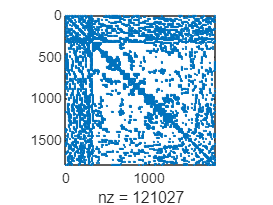

clear
close all

filepath = "./Sims/matrices";
prefix = "SolidBeam-Tet10-FreeFree";
K = import_stiffness(strjoin([filepath, prefix + "_STIF1.mtx"], filesep));
M = import_mass(strjoin([filepath,      prefix + "_MASS2.mtx"], filesep));
f = import_load(strjoin([filepath,      prefix + "_LOAD3.mtx"], filesep));
[K, M, f] = prepare_linear_system(K, M, f);

spy(K);

bandwidth(K,"upper")

ans = 1802

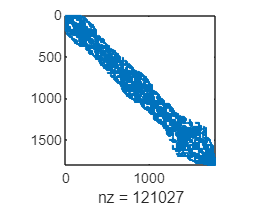

p = symrcm(K);
spy(K(p,p))

bandwidth(K(p,p),"upper")

ans = 338

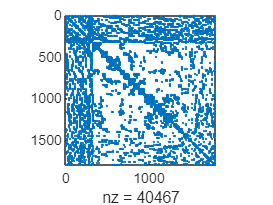

spy(M);


conditionNumber = condest(K)

conditionNumber = 6.1876e+18

null(full(K))

ans =    -0.0196   -0.0199   -0.0071   -0.0142    0.0252    0.0179
    0.0454   -0.0597   -0.0244   -0.0307   -0.0128    0.0127
    0.0450   -0.0228    0.0658   -0.0120    0.0105   -0.0189
   -0.0327   -0.0119    0.0083   -0.0040    0.0169    0.0201
    0.0454   -0.0597   -0.0244   -0.0307   -0.0128    0.0127
    0.0026   -0.0035    0.0303    0.0012    0.0298   -0.0751
   -0.0327   -0.0119    0.0083   -0.0040    0.0169    0.0201
   -0.0202   -0.0198    0.0528    0.0200   -0.0544    0.0237
   -0.0237   -0.0096   -0.0427    0.0653    0.0286    0.0031
   -0.0196   -0.0199   -0.0071   -0.0142    0.0252    0.0179


size(K)

ans =         1803        1803


numel(K)

ans = 3250809

nnz(K)

ans = 121027

nnz(K) / numel(K)

ans = 0.0372

eig(full(K), full(M))

ans = 	1.0e+11 *

   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0003
    0.0007


# Fixed - Fixed Beam

### Fixed-Fixed Beam2

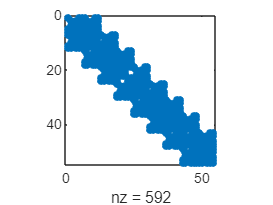

clear
close all

filepath = "./Sims/matrices";
prefix = "Beam-Beam2-FixedFixed";
K = import_stiffness(strjoin([filepath, prefix + "_STIF1.mtx"], filesep));
M = import_mass(strjoin([filepath,      prefix + "_MASS2.mtx"], filesep));
f = import_load(strjoin([filepath,      prefix + "_LOAD3.mtx"], filesep));
[K, M, f] = prepare_linear_system(K, M, f);

spy(K);

bandwidth(K,"upper")

ans = 11

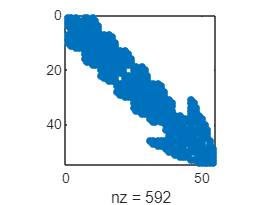

p = symrcm(K);
spy(K(p,p))

bandwidth(K(p,p),"upper")

ans = 15

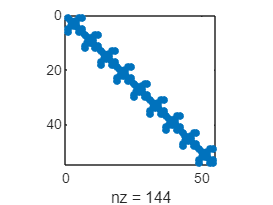

spy(M);


conditionNumber = condest(K)

conditionNumber = 2.2189e+04

null(full(K))


ans =

  54×0 empty double matrix



size(K)

ans =     54    54


numel(K)

ans = 2916

nnz(K)

ans = 592

nnz(K) / numel(K)

ans = 0.2030

eig(full(K), full(M))

ans = 	1.0e+09 *

    0.0111
    0.0111
    0.0331
    0.0580
    0.0580
    0.0979
    0.1291
    0.1582
    0.1582
    0.2787


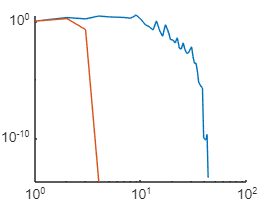


figure; hold on;
% Direct solver
x0 = K \ f;

% Iterative solver
[x1, ~, ~, ~, resvec1] = pcg(K, f, 1e-12, size(K,1));
plot(resvec1./norm(f))

% Preconditioned iterative solver
[L,U] = ilu(K);
[x2, ~, ~, ~, resvec2] = pcg(K, f, 1e-12, size(K,1), L, U);
plot(resvec2./norm(f))

ax = gca;
ax.XScale = "log";
ax.YScale = "log";

### Fixed-Fixed Beam3

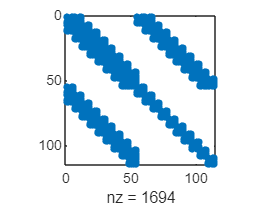

clear
close all

filepath = "./Sims/matrices";
prefix = "Beam-Beam3-FixedFixed";
K = import_stiffness(strjoin([filepath, prefix + "_STIF1.mtx"], filesep));
M = import_mass(strjoin([filepath,      prefix + "_MASS2.mtx"], filesep));
f = import_load(strjoin([filepath,      prefix + "_LOAD3.mtx"], filesep));
[K, M, f] = prepare_linear_system(K, M, f);

spy(K);

bandwidth(K,"upper")

ans = 65

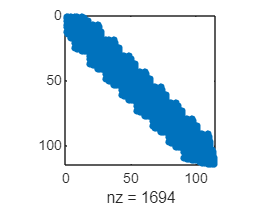

p = symrcm(K);
spy(K(p,p))

bandwidth(K(p,p),"upper")

ans = 18

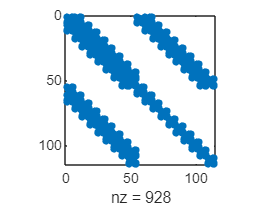

spy(M);


conditionNumber = condest(K)

conditionNumber = 1.1834e+05

null(full(K))


ans =

  114×0 empty double matrix



size(K)

ans =    114   114


numel(K)

ans = 12996

nnz(K)

ans = 1694

nnz(K) / numel(K)

ans = 0.1303

eig(full(K), full(M))

ans = 	1.0e+10 *

    0.0011
    0.0011
    0.0033
    0.0058
    0.0058
    0.0099
    0.0133
    0.0163
    0.0163
    0.0301


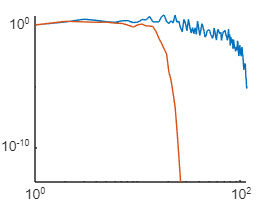


figure; hold on;
% Direct solver
x0 = K \ f;

% Iterative solver
[x1, ~, ~, ~, resvec1] = pcg(K, f, 1e-12, size(K,1));
plot(resvec1./norm(f))

% Preconditioned iterative solver
[L,U] = ilu(K);
[x2, ~, ~, ~, resvec2] = pcg(K, f, 1e-12, size(K,1), L, U);
plot(resvec2./norm(f))

ax = gca;
ax.XScale = "log";
ax.YScale = "log";

### Fixed-Fixed Hex8

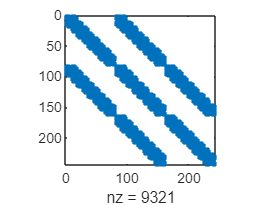

clear
close all

filepath = "./Sims/matrices";
prefix = "SolidBeam-Hex8-FixedFixed";
K = import_stiffness(strjoin([filepath, prefix + "_STIF1.mtx"], filesep));
M = import_mass(strjoin([filepath,      prefix + "_MASS2.mtx"], filesep));
f = import_load(strjoin([filepath,      prefix + "_LOAD3.mtx"], filesep));
[K, M, f] = prepare_linear_system(K, M, f);

spy(K);

bandwidth(K,"upper")

ans = 95

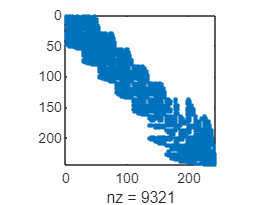

p = symrcm(K);
spy(K(p,p))

bandwidth(K(p,p),"upper")

ans = 65

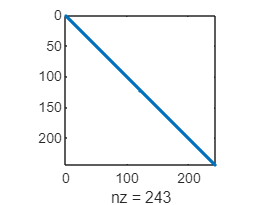

spy(M);


conditionNumber = condest(K)

conditionNumber = 4.0862e+03

null(full(K))


ans =

  243×0 empty double matrix



size(K)

ans =    243   243


numel(K)

ans = 59049

nnz(K)

ans = 9321

nnz(K) / numel(K)

ans = 0.1579

eig(full(K), full(M))

ans = 	1.0e+09 *

    0.0077
    0.0083
    0.0091
    0.0096
    0.0096
    0.0101
    0.0113
    0.0125
    0.0135
    0.0144


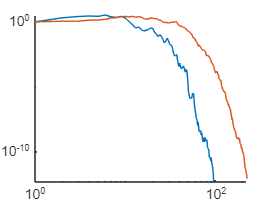


figure; hold on;
% Direct solver
x0 = K \ f;

% Iterative solver
[x1, ~, ~, ~, resvec1] = pcg(K, f, 1e-12, size(K,1));
plot(resvec1./norm(f))

% Preconditioned iterative solver
[L,U] = ilu(K);
[x2, ~, ~, ~, resvec2] = pcg(K, f, 1e-12, size(K,1), L, U);
plot(resvec2./norm(f))

ax = gca;
ax.XScale = "log";
ax.YScale = "log";

### Fixed-Fixed Hex20

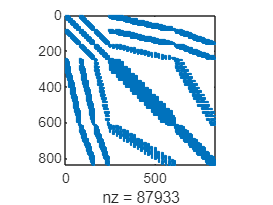

clear
close all

filepath = "./Sims/matrices";
prefix = "SolidBeam-Hex20-FixedFixed";
K = import_stiffness(strjoin([filepath, prefix + "_STIF1.mtx"], filesep));
M = import_mass(strjoin([filepath,      prefix + "_MASS2.mtx"], filesep));
f = import_load(strjoin([filepath,      prefix + "_LOAD3.mtx"], filesep));
[K, M, f] = prepare_linear_system(K, M, f);

spy(K);

bandwidth(K,"upper")

ans = 680

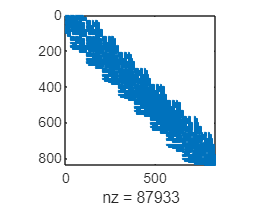

p = symrcm(K);
spy(K(p,p))

bandwidth(K(p,p),"upper")

ans = 158

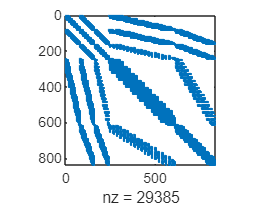

spy(M);


conditionNumber = condest(K)

conditionNumber = 3.1623e+04

null(full(K))


ans =

  837×0 empty double matrix



size(K)

ans =    837   837


numel(K)

ans = 700569

nnz(K)

ans = 87933

nnz(K) / numel(K)

ans = 0.1255

eig(full(K), full(M))

ans = 	1.0e+10 *

    0.0011
    0.0011
    0.0034
    0.0060
    0.0060
    0.0100
    0.0137
    0.0169
    0.0169
    0.0308


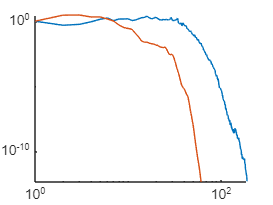


figure; hold on;
% Direct solver
x0 = K \ f;

% Iterative solver
[x1, ~, ~, ~, resvec1] = pcg(K, f, 1e-12, size(K,1));
plot(resvec1./norm(f))

% Preconditioned iterative solver
[L,U] = ilu(K);
[x2, ~, ~, ~, resvec2] = pcg(K, f, 1e-12, size(K,1), L, U);
plot(resvec2./norm(f))

ax = gca;
ax.XScale = "log";
ax.YScale = "log";

### Fixed-Fixed Tet4

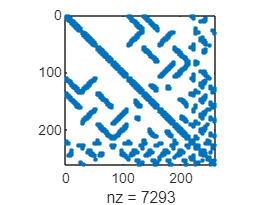

clear
close all

filepath = "./Sims/matrices";
prefix = "SolidBeam-Tet4-FixedFixed";
K = import_stiffness(strjoin([filepath, prefix + "_STIF1.mtx"], filesep));
M = import_mass(strjoin([filepath,      prefix + "_MASS2.mtx"], filesep));
f = import_load(strjoin([filepath,      prefix + "_LOAD3.mtx"], filesep));
[K, M, f] = prepare_linear_system(K, M, f);

spy(K);

bandwidth(K,"upper")

ans = 242

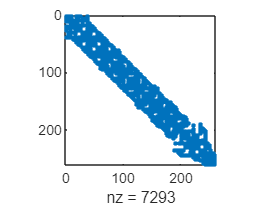

p = symrcm(K);
spy(K(p,p))

bandwidth(K(p,p),"upper")

ans = 47

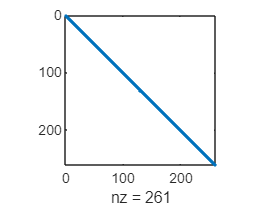

spy(M);


conditionNumber = condest(K)

conditionNumber = 3.7273e+03

null(full(K))


ans =

  261×0 empty double matrix



size(K)

ans =    261   261


numel(K)

ans = 68121

nnz(K)

ans = 7293

nnz(K) / numel(K)

ans = 0.1071

eig(full(K), full(M))

ans = 	1.0e+10 *

    0.0016
    0.0016
    0.0051
    0.0080
    0.0082
    0.0101
    0.0202
    0.0211
    0.0212
    0.0391


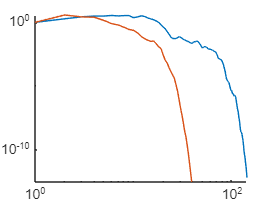


figure; hold on;
% Direct solver
x0 = K \ f;

% Iterative solver
[x1, ~, ~, ~, resvec1] = pcg(K, f, 1e-12, size(K,1));
plot(resvec1./norm(f))

% Preconditioned iterative solver
[L,U] = ilu(K);
[x2, ~, ~, ~, resvec2] = pcg(K, f, 1e-12, size(K,1), L, U);
plot(resvec2./norm(f))

ax = gca;
ax.XScale = "log";
ax.YScale = "log";

### Fixed-Fixed Tet10

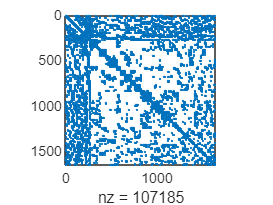

clear
close all

filepath = "./Sims/matrices";
prefix = "SolidBeam-Tet10-FixedFixed";
K = import_stiffness(strjoin([filepath, prefix + "_STIF1.mtx"], filesep));
M = import_mass(strjoin([filepath,      prefix + "_MASS2.mtx"], filesep));
f = import_load(strjoin([filepath,      prefix + "_LOAD3.mtx"], filesep));
[K, M, f] = prepare_linear_system(K, M, f);

spy(K);

bandwidth(K,"upper")

ans = 1649

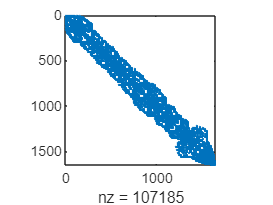

p = symrcm(K);
spy(K(p,p))

bandwidth(K(p,p),"upper")

ans = 287

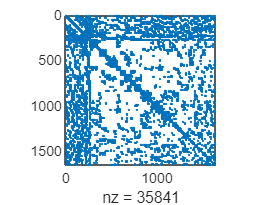

spy(M);


conditionNumber = condest(K)

conditionNumber = 3.6446e+04

null(full(K))


ans =

  1653×0 empty double matrix



size(K)

ans =         1653        1653


numel(K)

ans = 2732409

nnz(K)

ans = 107185

nnz(K) / numel(K)

ans = 0.0392

eig(full(K), full(M))

ans = 	1.0e+11 *

    0.0001
    0.0001
    0.0004
    0.0006
    0.0006
    0.0010
    0.0014
    0.0017
    0.0017
    0.0032



figure; hold on;
% Direct solver
x0 = K \ f;

% Iterative solver
[x1, ~, ~, ~, resvec1] = pcg(K, f, 1e-12, size(K,1));

plot(resvec1./norm(f))

% Preconditioned iterative solver
[L,U] = ilu(K);
[x2, ~, ~, ~, resvec2] = pcg(K, f, 1e-12, size(K,1), L, U);

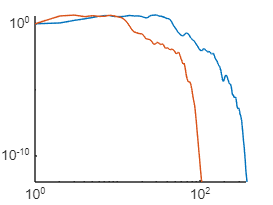

plot(resvec2./norm(f))

ax = gca;
ax.XScale = "log";
ax.YScale = "log";

# Mesh Quality

## Poor Quality Pave Quad Mesh

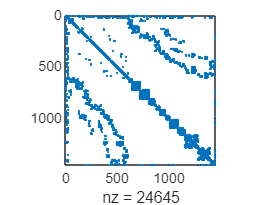

clear
close all

filepath = "./Sims/matrices";
prefix = "Poor_Pave_QuadMesh";
K = import_stiffness(strjoin([filepath, prefix + "_STIF1.mtx"], filesep));
M = import_mass(strjoin([filepath,      prefix + "_MASS2.mtx"], filesep));
f = import_load(strjoin([filepath,      prefix + "_LOAD3.mtx"], filesep));
[K, M, f] = prepare_linear_system(K, M, f);
f = rand(size(K,1), 1);

spy(K);

bandwidth(K,"upper")

ans = 1403

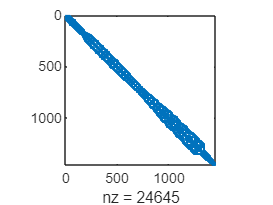

p = symrcm(K);
spy(K(p,p))

bandwidth(K(p,p),"upper")

ans = 99

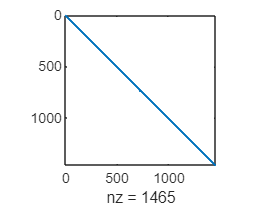

spy(M);


conditionNumber = condest(K)

conditionNumber = 6.2662e+08

null(full(K))


ans =

  1461×0 empty double matrix



size(K)

ans =         1461        1461


numel(K)

ans = 2134521

nnz(K)

ans = 24645

nnz(K) / numel(K)

ans = 0.0115

eig(full(K), full(M))

ans = 	1.0e+12 *

    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002



figure; hold on;
% Direct solver
x0 = K \ f;

% Iterative solver
[x1, ~, ~, ~, resvec1] = pcg(K, f, 1e-12, size(K,1));

plot(resvec1./norm(f))

% Preconditioned iterative solver
[L,U] = ilu(K);
[x2, ~, ~, ~, resvec2] = pcg(K, f, 1e-12, size(K,1), L, U);

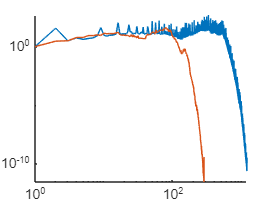

plot(resvec2./norm(f))

ax = gca;
ax.XScale = "log";
ax.YScale = "log";

## Quality Pave Quad Mesh

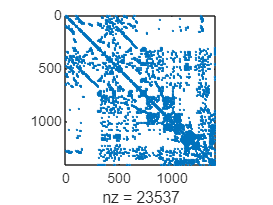

clear
close all

filepath = "./Sims/matrices";
prefix = "Quality_Pave_QuadMesh";
K = import_stiffness(strjoin([filepath, prefix + "_STIF1.mtx"], filesep));
M = import_mass(strjoin([filepath,      prefix + "_MASS2.mtx"], filesep));
f = import_load(strjoin([filepath,      prefix + "_LOAD3.mtx"], filesep));
[K, M, f] = prepare_linear_system(K, M, f);
f = rand(size(K,1), 1);

spy(K);

bandwidth(K,"upper")

ans = 1275

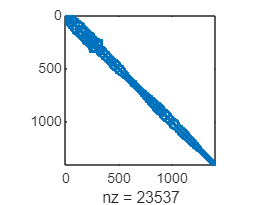

p = symrcm(K);
spy(K(p,p))

bandwidth(K(p,p),"upper")

ans = 106

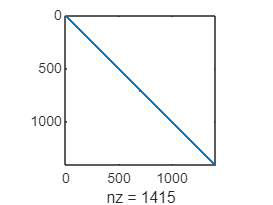

spy(M);


conditionNumber = condest(K)

conditionNumber = 2.8601e+08

null(full(K))


ans =

  1411×0 empty double matrix



size(K)

ans =         1411        1411


numel(K)

ans = 1990921

nnz(K)

ans = 23537

nnz(K) / numel(K)

ans = 0.0118

eig(full(K), full(M))

ans = 	1.0e+11 *

    0.0000
    0.0001
    0.0001
    0.0005
    0.0009
    0.0012
    0.0015
    0.0016
    0.0023
    0.0025



figure; hold on;
% Direct solver
x0 = K \ f;

% Iterative solver
[x1, ~, ~, ~, resvec1] = pcg(K, f, 1e-12, size(K,1));

plot(resvec1./norm(f))

% Preconditioned iterative solver
[L,U] = ilu(K);
[x2, ~, ~, ~, resvec2] = pcg(K, f, 1e-12, size(K,1), L, U);

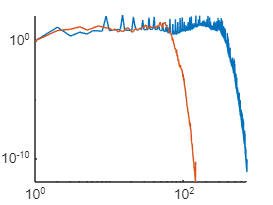

plot(resvec2./norm(f))

ax = gca;
ax.XScale = "log";
ax.YScale = "log";

## Quality Semi-structured Quad Mesh

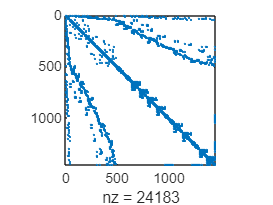

clear
close all

filepath = "./Sims/matrices";
prefix = "Quality_SemiStruct_QuadMesh";
K = import_stiffness(strjoin([filepath, prefix + "_STIF1.mtx"], filesep));
M = import_mass(strjoin([filepath,      prefix + "_MASS2.mtx"], filesep));
f = import_load(strjoin([filepath,      prefix + "_LOAD3.mtx"], filesep));
[K, M, f] = prepare_linear_system(K, M, f);
f = rand(size(K,1), 1);

spy(K);

bandwidth(K,"upper")

ans = 1405

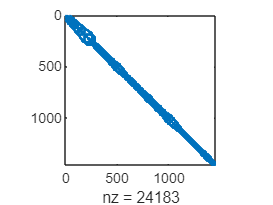

p = symrcm(K);
spy(K(p,p))

bandwidth(K(p,p),"upper")

ans = 79

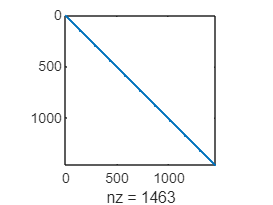

spy(M);


conditionNumber = condest(K)

conditionNumber = 3.3034e+08

null(full(K))


ans =

  1459×0 empty double matrix



size(K)

ans =         1459        1459


numel(K)

ans = 2128681

nnz(K)

ans = 24183

nnz(K) / numel(K)

ans = 0.0114

eig(full(K), full(M))

ans = 	1.0e+11 *

    0.0000
    0.0001
    0.0001
    0.0005
    0.0009
    0.0010
    0.0014
    0.0015
    0.0016
    0.0020



figure; hold on;
% Direct solver
x0 = K \ f;

% Iterative solver
[x1, ~, ~, ~, resvec1] = pcg(K, f, 1e-12, size(K,1));

plot(resvec1./norm(f))

% Preconditioned iterative solver
[L,U] = ilu(K);
[x2, ~, ~, ~, resvec2] = pcg(K, f, 1e-12, size(K,1), L, U);

plot(resvec2./norm(f))


x3 =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


resvec = 	1.0e+307 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


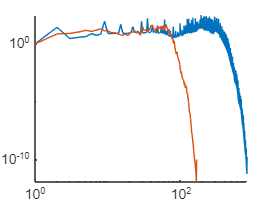

ax = gca;
ax.XScale = "log";
ax.YScale = "log";